# Taller 1, punto 6: perceptron sobre las particiones de banknote

clear; close all; clc
load banknote_splits.mat

## Parametros

regla = 3; umbral = 0; salida = [-1 1]; max_epocas = 200; semilla = 1;
alphas = [0.01 0.05 0.1 0.5 1];

## Entrenamiento con y sin escalar las entradas

R = table();
for escalar = [false true]
    for k = 1:4
        Xtr = S(k).Xtr; Xte = S(k).Xte;
        dtr = 2*S(k).ytr - 1;  dte = 2*S(k).yte - 1;
        if escalar
            mn = min(Xtr); mx = max(Xtr);
            Xtr = (Xtr - mn) ./ (mx - mn);  Xte = (Xte - mn) ./ (mx - mn);
        end
        for a = alphas
            [w, b, ep, conv] = perceptron(Xtr, dtr, regla, a, umbral, salida, max_epocas, semilla);
            acc_tr = 100*mean(predecir(Xtr, w, b, umbral, salida) == dtr);
            acc_te = 100*mean(predecir(Xte, w, b, umbral, salida) == dte);
            R = [R; table(escalar, k, {sprintf('%d-%d', 100*S(k).p, 100-100*S(k).p)}, a, ep, conv, acc_tr, acc_te, ...
                 'VariableNames', {'Escalado','k','Particion','Alpha','Epocas','Convergio','Exact_train','Exact_test'})];
        end
    end
end
R

R = 40×8 table
    Escalado    k    Particion    Alpha    Epocas    Convergio    Exact_train    Exact_test
    ________    _    _________    _____    ______    _________    ___________    __________

     false      1    {'60-40'}    0.01      200        false        98.663         98.907  
     false      1    {'60-40'}    0.05      200        false        98.906         99.271  
     false      1    {'60-40'}     0.1      200        false        98.906         99.271  
     false      1    {'60-40'}     0.5      200        false        99.028         99.089  
     false      1    {'60-40'}       1      200        false        98.785         99.271  
     false      2    {'70-30'}    0.01      200        false        98.958         99.029  
     false      2    {'70-30'}    0.05      200        false        98.021         98.058  
     false      2    {'70-30'}     0.1      200        false        99.167         99.029  
     false      2    {'70-30'}     0.5      200        false    

## Exactitud en test contra alpha

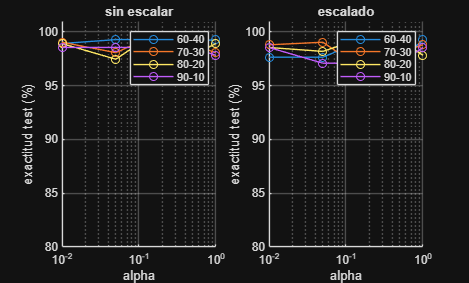

figure
titulos = {'sin escalar', 'escalado'};
for e = 1:2
    subplot(1,2,e); hold on
    for k = 1:4
        m = R.Escalado == (e==2) & R.k == k;
        plot(R.Alpha(m), R.Exact_test(m), '-o', 'DisplayName', R.Particion{find(m,1)});
    end
    set(gca, 'XScale', 'log'); grid on; ylim([80 101]); legend
    xlabel('alpha'); ylabel('exactitud test (%)'); title(titulos{e});
end

## Matriz de confusion del mejor caso

[~, i] = max(R.Exact_test);
R(i, :)

ans = 1×8 table
    Escalado    k    Particion    Alpha    Epocas    Convergio    Exact_train    Exact_test
    ________    _    _________    _____    ______    _________    ___________    __________

     false      1    {'60-40'}    0.05      200        false        98.906         99.271  


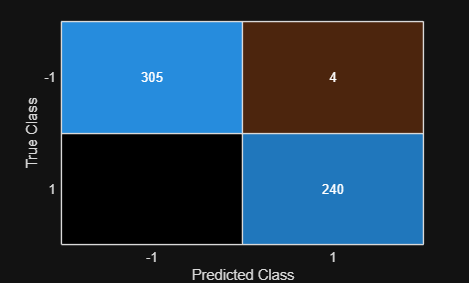

k = R.k(i);
Xtr = S(k).Xtr; Xte = S(k).Xte; dtr = 2*S(k).ytr - 1; dte = 2*S(k).yte - 1;
if R.Escalado(i)
    mn = min(Xtr); mx = max(Xtr);
    Xtr = (Xtr - mn) ./ (mx - mn);  Xte = (Xte - mn) ./ (mx - mn);
end
[w, b] = perceptron(Xtr, dtr, regla, R.Alpha(i), umbral, salida, max_epocas, semilla);
figure
confusionchart(dte, predecir(Xte, w, b, umbral, salida))